# **Otonom Araçları için kaza riski analizi**

## **Alabileceğimiz girişler:**

**Arabanın hızı**, Arabanın ağırlığı, **kalan mesafe**, hava durumu

## **Rules tables:**

**Dist\Speed  Slow           Fast            VeryFast**

**Far**               VLow          Low             Average

**Close**           Low            Average      High

**VeryClose   **Aaverage    High            VH

%global X mu_X mu_xi;
altsinir_x = 0;
ustsinir_x = 100;
altsinir_y = 0;
ustsinir_y = 100;
altsinir_z = 0;
ustsinir_z = 100;

xi = 30;
yi = 3;
zi = 0;

XX = altsinir_x:ustsinir_x;
YY = altsinir_y:ustsinir_y;
%ZZ = altsinir_z:ustsinir_z;
z = zeros(size(XX,2),size(YY,2));

tic
parfor i=1:size(XX,2)
    z_tmp = zeros(1,size(YY,2))
    for j=1:size(YY,2)
        toplam_alan = 0;
        xi=XX(i);
        yi=YY(j);
        %% Inputs and Outputs Membership Functions
        % input 1
        [x_S, mu_S, mu_xi_S] = Yamuk(altsinir_x,0,0,20,40,ustsinir_x,xi);
        [x_F, mu_F, mu_xi_F] = Yamuk(altsinir_x,20,40,60,80,ustsinir_x,xi);
        [x_VF, mu_VF, mu_xi_VF] = Yamuk(altsinir_x,60,80,100,100,ustsinir_x,xi); 
        
        % input 2
        [y_F, mu_F, mu_yi_F] = Yamuk(altsinir_y,0,0,20,40,ustsinir_y,yi);
        [y_C, mu_C, mu_yi_C] = Yamuk(altsinir_y,20,40,60,80,ustsinir_y,yi);
        [y_VC, mu_VC, mu_yi_VC] = Yamuk(altsinir_y,60,80,100,100,ustsinir_y,yi);
        
        % output
        [z_VL, mu_VL, dump] = Yamuk(altsinir_z,0,0,10,20,ustsinir_z,zi);
        [z_L, mu_L, dump] = Yamuk(altsinir_z,10,20,30,40,ustsinir_z,zi);
        [z_A, mu_A, dump] = Yamuk(altsinir_z,30,40,50,60,ustsinir_z,zi);
        [z_H, mu_H, dump] = Yamuk(altsinir_z,50,60,70,80,ustsinir_z,zi);
        [z_VH, mu_VH, dump] = Yamuk(altsinir_z,70,80,100,100,ustsinir_z,zi);
        
        ZZ = z_VL; X = z_VL;
        
        %% Fuzzy rules
        
        mu_kural1 = min(mu_xi_S,mu_yi_F);
        mu_kural2 = min(mu_xi_S,mu_yi_C);
        mu_kural3 = min(mu_xi_S,mu_yi_VC);

        mu_kural4 = min(mu_xi_F,mu_yi_F);
        mu_kural5 = min(mu_xi_F,mu_yi_C);
        mu_kural6 = min(mu_xi_F,mu_yi_VC);
        
        mu_kural7 = min(mu_xi_VF,mu_yi_F);
        mu_kural8 = min(mu_xi_VF,mu_yi_C);
        mu_kural9 = min(mu_xi_VF,mu_yi_VC);
        
        %% Results
        
        mu_sonuc1 = mu_kural1*mu_VL;
        mu_sonuc2 = mu_kural2*mu_L;
        mu_sonuc3 = mu_kural3*mu_A;
        mu_sonuc4 = mu_kural4*mu_L;
        mu_sonuc5 = mu_kural5*mu_A;
        mu_sonuc6 = mu_kural6*mu_H;
        mu_sonuc7 = mu_kural7*mu_A;
        mu_sonuc8 = mu_kural8*mu_H;
        mu_sonuc9 = mu_kural9*mu_VH;
        
        %plot(X,mu_sonuc1,X,mu_sonuc2,X,mu_sonuc3,X,mu_sonuc4);
        
        %% Aggregation
        mu_birlestirme_1 = max(max(mu_sonuc1,mu_sonuc2),max(mu_sonuc3,mu_sonuc4));
        mu_birlestirme_2 = max(max(mu_sonuc5,mu_sonuc6),max(mu_sonuc7,mu_sonuc8));
        mu_birlestirme = max(max(mu_birlestirme_1,mu_birlestirme_2),mu_sonuc9);

        %plot(X,mu_birlestirme);
        
        %% defuzzification
        toplam_alan = sum(mu_birlestirme);
        if toplam_alan == 0
            'Toplam Alan sifir!';
        end
        %z(i,j) = sum(mu_birlestirme.*ZZ)/toplam_alan;
        z_tmp(j) = sum(mu_birlestirme.*ZZ)/toplam_alan;
    end %j
    z(i,:) = z_tmp;
end %i

Starting parallel pool (parpool) using the 'local' profile ...
connected to 8 workers.


toc

Elapsed time is 229.146689 seconds.


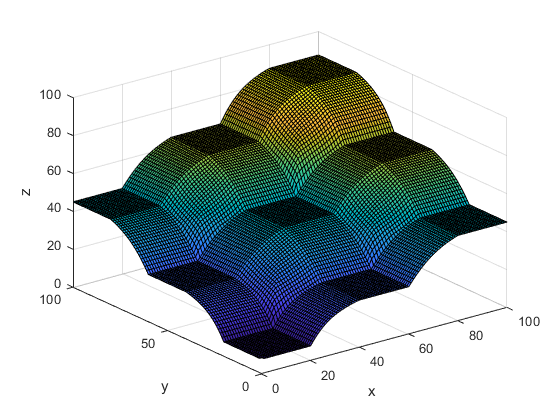

[x,y] = meshgrid(XX,YY);
surf(x,y,z')
xlabel('x');
ylabel('y');
zlabel('z');